function [Vavg, Omega] = rcsj_iv_curve(R,C,T,Ic,f_drive,gammaAC,tSim,dt,ensembleRuns,discard_fraction,gammaDC_vals,frac_4pi) 
    %% Physical Constants
    e    = 1.602176634e-19;    % Electron charge [C]
    hbar = 1.054571817e-34;    % Reduced Planck constant [J*s]
    kB   = 1.380649e-23;       % Boltzmann constant [J/K]

    % Initial conditions (for first run)
    phi0 = 0;  % initial phase (radians)
    v0   = 0;  % initial voltage (normalized, i.e. dphi/dtau)
    noiseAmp = 0; %initial value

    Ncurrents = length(gammaDC_vals);
    Vavg = zeros(1, Ncurrents);  % To store time-averaged (normalized) voltage per bias
    
    %% Derived Parameters   
    beta_c = (2 * e * Ic * R^2 * C) / hbar; % Stewart-McCumber parameter:
    fprintf('Stewart-McCumber parameter, beta_c = %.3f\n', beta_c);       
    omega_p = sqrt((2 * e * Ic) / (hbar * C));  % [rad/s] % Plasma frequency:
    fprintf('Plasma frequency = %.3f GHz\n', omega_p/(2*pi*1e9));       
    omega_drive = 2 * pi * f_drive;  % [rad/s] % Microwave (drive) frequency:
    fprintf('Microwave drive frequency = %.3f GHz\n', omega_drive/(2*pi*1e9));        
    Omega = omega_drive / omega_p; % Dimensionless drive frequency:
    if f_drive==0
        Omega = 1;
    end
    fprintf('Dimensionless drive frequency, Omega = %.3f\n', Omega);       
    EJ = (hbar * Ic) / (2 * e); % Josephson energy:
    fprintf('Josephson energy, EJ = %.3f eV\n', EJ/e);
   
    %% Loop over DC bias values
    wb = waitbar(0, 'Starting simulation');
    for k = 1:Ncurrents
        gammaDC = gammaDC_vals(k);
        voltage_runs = zeros(1, ensembleRuns);
        parfor r = 1:ensembleRuns
            [tau_, ~, vVals] = rsj_heun_run(gammaDC, gammaAC, Omega, beta_c, phi0, v0, tSim, dt, noiseAmp, frac_4pi);
            idxStart = floor(discard_fraction * length(tau_));  % Discard initial transient (e.g., first 30% of simulation)
            steady_v = vVals(idxStart:end);
            voltage_runs(r) = mean(steady_v);
        end
        Vavg(k) = mean(voltage_runs);
        v0 = Vavg(k);
        S = 2 * e * v0 / R * coth(e * v0 / (2 * kB * T));   %Noise spectral density A^2/Hz
        noiseAmp = sqrt(2 * S / (Ic^2 * omega_p*dt)); % dimless
        %fprintf('Dimensionless noise amplitude = %.3e\n', noiseAmp);
        waitbar(k/Ncurrents, wb, sprintf('Progress: %d %%', floor(100*k/Ncurrents)));
    end
    close(wb)
end

function [tau, phiVals, vVals] = rsj_heun_run(gammaDC, gammaAC, Omega, beta_c, phi0, v0, tSim, dt, noiseAmp, frac_4pi)
    % RSJ_HEUN_RUN integrates the stochastic RSJ model using the Heun (explicit trapezoidal) method for SDEs.
    % The dimensionless system is:
    %   dphi/dtau = v
    %   dv/dtau   = gammaDC + gammaAC*sin(Omega*tau) - sin(phi) - (1/beta_c)*v + noise
    % where the noise is (noiseAmp * randn) * dt in each step.
    N = floor(tSim/Omega/dt); %floor(tSim/dt);
    tau = (0:N)*dt;
    phiVals = zeros(1, N+1);
    vVals   = zeros(1, N+1);

    % Initial conditions
    phiVals(1) = phi0;
    vVals(1)   = v0;

    for i = 1:N
        % Current states:
        phi_n = phiVals(i);
        v_n   = vVals(i);
        tau_n = tau(i);

        % Wiener increment:
        dW = sqrt(dt)*randn;   % single dimension => for dv eqn

        % Evaluate drift at (phi_n, v_n)
        fphi_n = v_n;
        fv_n   = gammaDC + gammaAC*sin(Omega*tau_n) - (sin(phi_n)*(1-frac_4pi)+sin(phi_n/2)*frac_4pi) - (1/beta_c)*v_n;

        % Predictor (Euler step)
        phi_star = phi_n + fphi_n*dt ;   % no direct noise in phi eqn
        v_star   = v_n   + fv_n*dt   + noiseAmp*dW;

        % Evaluate drift at star
        tau_star  = tau_n + dt;
        fphi_star = v_star;
        fv_star   = gammaDC + gammaAC*sin(Omega*tau_star) - (sin(phi_star)*(1-frac_4pi)+sin(phi_star/2)*frac_4pi) - (1/beta_c)*v_star;

        % Corrector
        phiVals(i+1) = phi_n + 0.5*(fphi_n + fphi_star)*dt ;
        vVals(i+1)   = v_n   + 0.5*(fv_n   + fv_star)  *dt + noiseAmp*dW;
    end
end

%% Experimental Parameters (SI units)
R       = 120;              % Shunt resistance in Ohms
C       = 5e-14;            % Junction capacitance in Farads
T       = 0.080;            % Temperature in Kelvin
Ic      = 0.4e-6;           % Critical current in Amperes
f_drive = 5e9;              % RF (AC) drive frequency in Hz
gammaAC = 0.2;          % Normalized AC amplitude (I_AC/Ic)
gammaDC_vals = linspace(0, 1.6, 200);  % Normalized DC bias current range (I_DC/Ic)
frac_4pi = 0.5;             % [0..1] fraction of the CPR which is 4-pi-periodic. If frac_4pi = 0, CPR is only 2-pi-periodic
                            % (sin(phi)*(1-frac_4pi)+sin(phi/2)*frac_4pi)

%% Simulation Parameters
tSim = 300;            % Total simulation time for each Voltage (dimensionless)
dt   = 0.001;          % Time step (dimensionless)
ensembleRuns = 8;       % Number of runs per current point for ensemble averaging (maybe use No. of cores of your computer)
discard_fraction =2/3; % Discard initial transient of voltage oscillations

[Vavg, Omega] = rcsj_iv_curve(R,C,T,Ic,f_drive,gammaAC,tSim,dt,ensembleRuns,discard_fraction,gammaDC_vals,frac_4pi);

Stewart-McCumber parameter, beta_c = 0.875
Plasma frequency = 24.814 GHz
Microwave drive frequency = 5.000 GHz
Dimensionless drive frequency, Omega = 0.201
Josephson energy, EJ = 0.001 eV


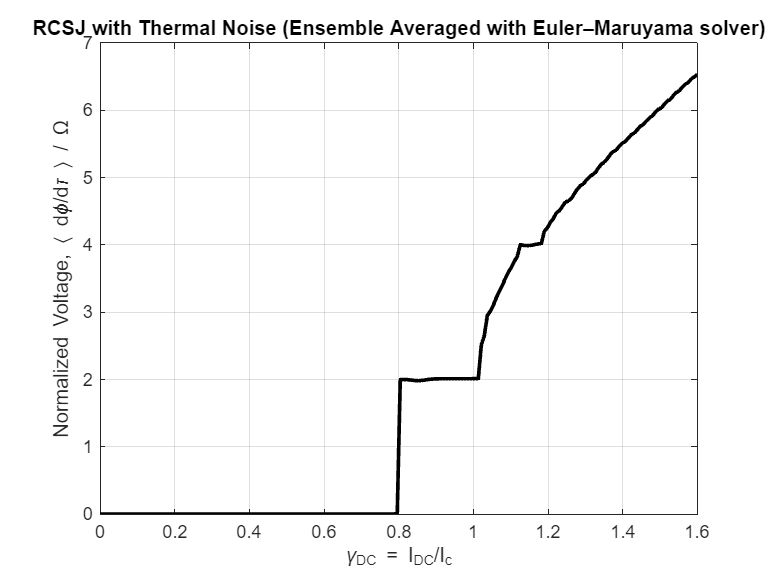

    %% Plot the I-V Curve (Normalized)
    figure;
    % In our normalized model, the voltage is given by dphi/dtau.
    % In the phase-locked regime, <dphi/dtau> = n*Omega so that normalized voltage divided by Omega gives the step number.
    plot(gammaDC_vals, Vavg/Omega, 'k', 'LineWidth', 2);
    xlabel('\gamma_{DC} = I_{DC}/I_c');
    ylabel('Normalized Voltage, \langle d\phi/d\tau \rangle / \Omega');
    title('RCSJ with Thermal Noise (Ensemble Averaged with Euler–Maruyama solver)');
    grid on;